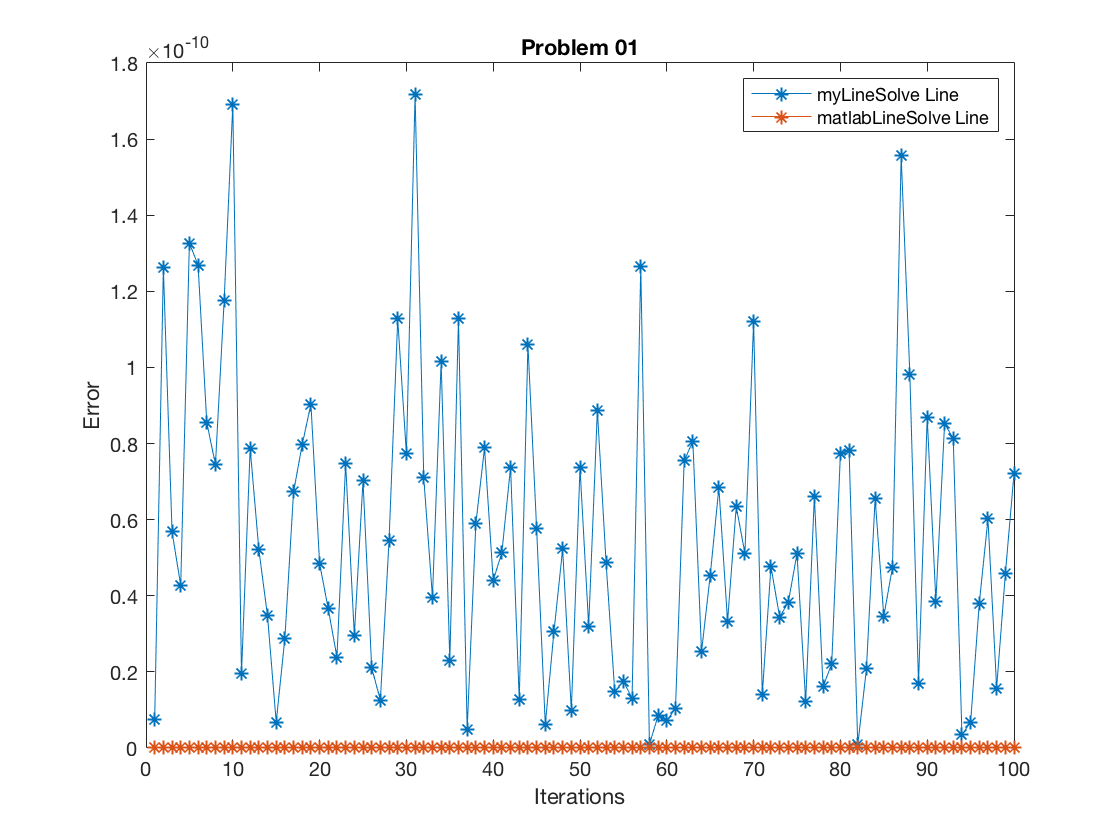

% Problem 01A
X = 1:100;
A = rand(100);
x = rand(100,1);
b = A * x;
result = my_linsolve(A,b);
temp = abs(x - result);
result2 = linsolve(A,b);
temp2 = abs(x - result2);

% Graph Making
% From the graph, we can see that the bult in function, linsolve(A,b),
% yields a more consistent and less error than our own function.
plot(X,temp, '-*',X,temp2,'-*');
title('Problem 01');
legend('myLineSolve Line','matlabLineSolve Line');
xlabel('Iterations');
ylabel('Error');


% Problem 01B


function x = my_linsolve(A,b)
n = size(A,1);
A = [A,b];

%introduce zeros below diagonaol
for j = 1:n
    for i = j+1:n
    A(i,:) = A(i,:) - A(i,j)/A(j,j) * A(j,:);
    A(i,j) = 0;
    end
end

%Introduce zeros above diagonal
for j=n:-1:1
    for i=1:j-1
        A(i,:) = A(i,:) - A(i,j)/A(j,j)*A(j,:);
        A(i,j) = 0;
    end
end

%solve diagonal linear systems
x = A(1:n,n+1) ./ diag(A(1:n,1:n));
end

